%% =========================================================================
%  ELECTROMAGNETICS EXAM TEMPLATE - E25
%  Ready-to-use template for solving exam problems
%  =========================================================================
%
%  BEFORE EXAM: 
%    1. Add helpers to path
%    2. Run this cell to verify everything works
%    3. Delete example values, keep structure
%
%  DURING EXAM:
%    1. Find the problem type in the table below
%    2. Go to that section
%    3. Fill in your values
%    4. Run the cell
%
%% =========================================================================

%% SETUP - RUN THIS FIRST
clear; clc;
addpath('C:\Users\Mads2\DTU\3.semester\Electromagnetics\Helpers');

% Physical Constants (given in exam)
c0   = 2.99792458e8;          % Speed of light [m/s]
eps0 = 8.854187817e-12;       % Vacuum permittivity [F/m]
mu0  = 4*pi*1e-7;             % Vacuum permeability [H/m]
eta0 = sqrt(mu0/eps0);        % Free space impedance ≈ 377 Ω

fprintf('✓ Setup complete. Constants loaded.\n');

✓ Setup complete. Constants loaded.


fprintf('  c0 = %.4e m/s\n', c0);

  c0 = 2.9979e+08 m/s


fprintf('  η0 = %.2f Ω\n', eta0);

  η0 = 376.73 Ω


## =========================================================================


%  QUICK REFERENCE: PROBLEM TYPE → SECTION
%% =========================================================================
%{
┌─────────────────────────────────────────┬─────────────────┐
│ PROBLEM KEYWORDS                        │ GO TO SECTION   │
├─────────────────────────────────────────┼─────────────────┤
│ VSWR, |Γ|, reflection coefficient       │ TL-1            │
│ Z_in (input impedance)                  │ TL-2            │
│ Find Z_L from Γ_in                      │ TL-3            │
│ Find Z_L from VSWR + V_min position     │ TL-4            │
│ λ/4 transformer                         │ TL-5            │
│ Stub matching, find d and ℓ             │ TL-6            │
│ Stub to realize jX (inductor/capacitor) │ TL-7            │
│ Smith chart                             │ TL-8            │
├─────────────────────────────────────────┼─────────────────┤
│ Wavelength λ in medium                  │ MED-1           │
│ Skin depth, good conductor              │ MED-2           │
│ Loss tangent, classification            │ MED-3           │
│ Wave parameters (α, β, η)               │ MED-4           │
├─────────────────────────────────────────┼─────────────────┤
│ H-field from E-field                    │ PW-1            │
│ Poynting vector, power density          │ PW-2            │
│ Incident power on surface               │ PW-3            │
│ Frequency from phase term               │ PW-4            │
│ Plane wave verification                 │ PW-5            │
├─────────────────────────────────────────┼─────────────────┤
│ Polarization type (Linear/Circular)     │ POL-1           │
│ Handedness (RHCP/LHCP)                  │ POL-1           │
│ Axial ratio                             │ POL-1           │
├─────────────────────────────────────────┼─────────────────┤
│ Fresnel Γ, τ at interface               │ INT-1           │
│ Brewster angle                          │ INT-2           │
│ Critical angle, TIR                     │ INT-3           │
│ Snell's law (θ_t)                       │ INT-4           │
│ Oblique incidence (TE/TM)               │ INT-5           │
├─────────────────────────────────────────┼─────────────────┤
│ Coulomb force                           │ STAT-1          │
│ Capacitance (parallel plate/coax/wire)  │ STAT-2          │
│ Solenoid inductance                     │ STAT-3          │
│ B-field from wire                       │ STAT-4          │
└─────────────────────────────────────────┴─────────────────┘
%}

%% =========================================================================
%  TRANSMISSION LINES
%% =========================================================================

%% TL-1: Basic Γ and VSWR
% Keywords: reflection coefficient, VSWR, |Γ|
% -------------------------------------------------------------------------
fprintf('\n=== TL-1: Basic Γ and VSWR ===\n');

% --- FILL IN YOUR VALUES ---
Z0 = 75;                    % Characteristic impedance [Ω]
ZL = 25 + 1j*30;            % Load impedance [Ω]

% --- CALCULATION ---
Gamma = (ZL - Z0) / (ZL + Z0);
VSWR = (1 + abs(Gamma)) / (1 - abs(Gamma));
[Gamma_mag, Gamma_ang] = rect2pol(Gamma);

fprintf('Γ = %.4f ∠ %.1f°\n', Gamma_mag, Gamma_ang);
fprintf('|Γ| = %.4f\n', abs(Gamma));
fprintf('VSWR = %.4f\n', VSWR);
fprintf('Power reflected = |Γ|² = %.1f%%\n', abs(Gamma)^2 * 100);

%% TL-2: Input Impedance Z_in
% Keywords: input impedance, TL with load, electrical length
% -------------------------------------------------------------------------
fprintf('\n=== TL-2: Input Impedance ===\n');

% --- FILL IN YOUR VALUES ---
Z0 = 75;                    % [Ω]
ZL = 100 + 1j*50;           % [Ω]
ell_lambda = 0.25;          % Length in wavelengths [λ]
% OR if given physical length and frequency:
% ell_m = 0.15;             % Physical length [m]
% f = 1e9;                  % Frequency [Hz]  
% u_p = 2e8;                % Phase velocity [m/s] (or c0 for air)
% lambda = u_p / f;
% ell_lambda = ell_m / lambda;

% --- USING HELPER ---
r = TLine(Z0, ZL, ell_lambda);

fprintf('Z_in = %.2f + j%.2f Ω\n', real(r.Z_in), imag(r.Z_in));
fprintf('Γ_in = %.4f ∠ %.1f°\n', abs(r.Gamma_in), rad2deg(angle(r.Gamma_in)));
fprintf('Γ_L = %.4f ∠ %.1f°\n', abs(r.Gamma_L), rad2deg(angle(r.Gamma_L)));
fprintf('VSWR = %.4f\n', r.VSWR);

%% TL-3: Find Z_L from Γ at Input (Q13-14 type)
% Keywords: Γ measured at input, find load, move toward load
% -------------------------------------------------------------------------
fprintf('\n=== TL-3: Find Z_L from Γ_in ===\n');

% --- FILL IN YOUR VALUES ---
Z0 = 75;                    % [Ω]
Gamma_in_mag = 0.539;       % |Γ| at input
Gamma_in_ang = 166;         % ∠Γ at input [degrees]
ell_lambda = 0.3;           % Line length [λ]

% --- USING HELPER ---
Gamma_in = Gamma_in_mag * exp(1j * deg2rad(Gamma_in_ang));
r = TLine('load', Z0, Gamma_in, ell_lambda);

fprintf('Γ_L = %.4f ∠ %.1f°\n', abs(r.Gamma_L), rad2deg(angle(r.Gamma_L)));
fprintf('Z_L = %.2f + j%.2f Ω\n', real(r.Z_L), imag(r.Z_L));

%% TL-4: Find Z_L from VSWR and V_min/V_max Position
% Keywords: standing wave measurement, first minimum, first maximum
% -------------------------------------------------------------------------
fprintf('\n=== TL-4: Z_L from VSWR + Position ===\n');

% --- FILL IN YOUR VALUES ---
Z0 = 50;                    % [Ω]
VSWR = 3.0;                 % VSWR (or use |Γ| or Γ_dB below)
% Gamma_mag = 0.5;          % Alternative: |Γ| directly
% Gamma_dB = -6;            % Alternative: Γ in dB
z_min = 0.1;                % First V_min position from load [λ]
% z_max = 0.2;              % Alternative: V_max position [λ]

% --- MANUAL CALCULATION ---
Gamma_mag = (VSWR - 1) / (VSWR + 1);
% For V_min: phase = π + 4π·z_min
% For V_max: phase = 4π·z_max
Gamma_phase = pi + 4*pi*z_min;  % Use this for V_min
% Gamma_phase = 4*pi*z_max;     % Use this for V_max

Gamma_L = Gamma_mag * exp(1j * Gamma_phase);
ZL = Z0 * (1 + Gamma_L) / (1 - Gamma_L);

[~, ang] = rect2pol(Gamma_L);
fprintf('|Γ_L| = %.4f\n', abs(Gamma_L));
fprintf('∠Γ_L = %.1f°\n', ang);
fprintf('Z_L = %.2f + j%.2f Ω\n', real(ZL), imag(ZL));

%% TL-5: Quarter-Wave Transformer Design
% Keywords: λ/4 matching, transformer, match Z_L to Z_in
% -------------------------------------------------------------------------
fprintf('\n=== TL-5: Quarter-Wave Transformer ===\n');

% --- FILL IN YOUR VALUES ---
Z_in_desired = 50;          % Desired input impedance [Ω]
ZL = 100;                   % Load impedance [Ω] (must be real)

% --- CALCULATION ---
Z0_transformer = sqrt(Z_in_desired * real(ZL));

fprintf('Required Z0 for λ/4 section = √(Z_in·Z_L) = %.2f Ω\n', Z0_transformer);

% Verify:
r = TLine('lambda/4', Z0_transformer, ZL);
fprintf('Verification: Z_in = %.2f Ω\n', real(r.Z_in));

%% TL-6: Single-Stub Matching (Q15-17 type)
% Keywords: stub tuner, match to Z0, find d and ℓ
% -------------------------------------------------------------------------
fprintf('\n=== TL-6: Single-Stub Matching ===\n');

% --- FILL IN YOUR VALUES ---
ZL = 142 + 1j*42.5;         % Load impedance [Ω]
Z0 = 75;                    % Line impedance [Ω]
stub_type = 'short';        % 'short' or 'open'
lambda = 0.1335;            % Wavelength [m] (optional, for physical length)

% --- USING HELPER ---
r = StubMatch(ZL, Z0, stub_type, lambda);

fprintf('d = %.4f λ', r.d);
if ~isempty(r.d_mm), fprintf(' = %.2f mm', r.d_mm); end
fprintf('\n');
fprintf('ℓ = %.4f λ', r.l);
if ~isempty(r.l_mm), fprintf(' = %.2f mm', r.l_mm); end
fprintf('\n');
fprintf('Alternative: d = %.4f λ, ℓ = %.4f λ\n', r.d_alt, r.l_alt);

%% TL-7: Stub to Realize jX (Inductor/Capacitor)
% Keywords: stub as reactive element, realize jωL, realize 1/jωC
% -------------------------------------------------------------------------
fprintf('\n=== TL-7: Stub as Reactive Element ===\n');

% --- FILL IN YOUR VALUES ---
Z_target = 1j*30;           % Target impedance (e.g., jωL) [Ω]
Z0_stub = 75;               % Stub characteristic impedance [Ω]
stub_type = 'short';        % 'short' or 'open'

% Optional: for physical length
f = 2e9;                    % Frequency [Hz]
u_p = 0.66 * c0;            % Phase velocity [m/s]
lambda = u_p / f;

% --- USING HELPER ---
r = TLine('stub', Z_target, Z0_stub, stub_type);

if strcmp(stub_type, 'short')
    len_lambda = r.short.len_lambda;
else
    len_lambda = r.open.len_lambda;
end

fprintf('Stub length = %.4f λ\n', len_lambda);
fprintf('Physical length = %.2f mm\n', len_lambda * lambda * 1e3);


## TL-8: Smith Chart Operations


% Keywords: normalized impedance, Γ on Smith chart
% -------------------------------------------------------------------------
fprintf('\n=== TL-8: Smith Chart ===\n');


=== TL-8: Smith Chart ===



% --- FILL IN YOUR VALUES ---
ZL = 100 - 1j*50;          % Load impedance [Ω]
Z0 = 50;                    % Reference impedance [Ω]

% --- CALCULATION ---
zL_norm = ZL / Z0;          % Normalized impedance
Gamma = (zL_norm - 1) / (zL_norm + 1);
yL_norm = 1 / zL_norm;      % Normalized admittance

fprintf('z_L (normalized) = %.3f + j%.3f\n', real(zL_norm), imag(zL_norm));

z_L (normalized) = 2.000 + j-1.000


fprintf('y_L (normalized) = %.3f + j%.3f\n', real(yL_norm), imag(yL_norm));

y_L (normalized) = 0.400 + j0.200


fprintf('Γ = %.4f ∠ %.1f°\n', abs(Gamma), rad2deg(angle(Gamma)));

Γ = 0.4472 ∠ -26.6°



=== Smith Chart Point ===
  Z0 = 50.00 Ohm
  ZL = 100.0000 -50.0000j Ohm
  zL (normalized) = 2.0000 -1.0000j
  Gamma = 0.4000 -0.2000j
  |Gamma| = 0.4472, angle = -26.57 deg



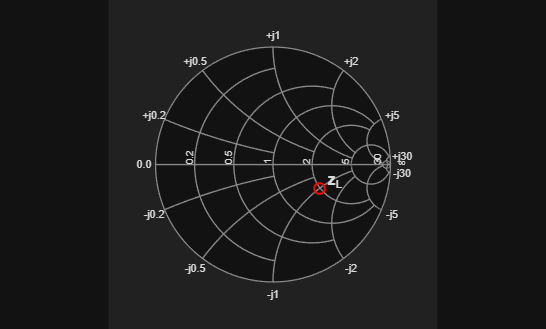


% Plot on Smith chart
smithchart_plot(Z0, ZL, 'z_L');


%% =========================================================================
%  MEDIUM PROPERTIES
%% =========================================================================


## MED-1: Wavelength in Medium


% Keywords: λ in dielectric, phase velocity
% -------------------------------------------------------------------------
fprintf('\n=== MED-1: Wavelength in Medium ===\n');

% --- FILL IN YOUR VALUES ---
eps_r = 2.1;                % Relative permittivity
f = 1550e6;                 % Frequency [Hz]
mu_r = 1;                   % Relative permeability (usually 1)
0.66*c0

% --- CALCULATION ---
lambda_0 = c0 / f;          % Free space wavelength
n = sqrt(eps_r * mu_r);     % Refractive index
lambda = lambda_0 / n;      % Wavelength in medium
u_p = c0 / n;               % Phase velocity

fprintf('λ₀ (free space) = %.4f m = %.2f cm\n', lambda_0, lambda_0*100);
fprintf('n = √(εr·μr) = %.4f\n', n);
fprintf('λ (in medium) = %.4f m = %.2f cm\n', lambda, lambda*100);
fprintf('u_p = %.4e m/s = %.2f·c₀\n', u_p, u_p/c0);


## MED-2: Skin Depth (Good Conductor)


% Keywords: skin depth, shielding, conductor
% -------------------------------------------------------------------------
fprintf('\n=== MED-2: Skin Depth ===\n');

% --- FILL IN YOUR VALUES ---
sigma = 58e6;               % Conductivity [S/m] (copper ≈ 58 MS/m)
f = 10e9;                   % Frequency [Hz]
mu_r = 1;                   % Relative permeability

% --- USING HELPER ---
r = Medium('skin', sigma, f, mu_r);

fprintf('Skin depth δ = %.4f μm\n', r.skin_depth * 1e6);
fprintf('For good shielding: t > 5δ = %.2f μm\n', 5 * r.skin_depth * 1e6);

% --- OR MANUAL ---
delta = sqrt(2 / (2*pi*f * mu0*mu_r * sigma));
fprintf('Manual check: δ = %.4f μm\n', delta * 1e6);

%% MED-3: Loss Tangent and Classification
% Keywords: loss tangent, tan δ, good dielectric, quasi-conductor
% -------------------------------------------------------------------------
fprintf('\n=== MED-3: Loss Tangent ===\n');

% --- FILL IN YOUR VALUES ---
eps_r = 3.5;                % Relative permittivity
sigma = 20e-3;              % Conductivity [S/m]
f = 1e9;                    % Frequency [Hz]

% --- USING HELPER ---
r = Medium(eps_r, sigma, f);

fprintf('tan(δ) = σ/(ω·ε) = %.4f\n', r.tan_delta);
fprintf('Classification: %s\n', r.classification);
% tan δ < 0.01: Good dielectric
% tan δ > 100: Good conductor
% Otherwise: Quasi-conductor

%% MED-4: Complete Wave Parameters
% Keywords: α, β, η, λ, u_p in lossy medium
% -------------------------------------------------------------------------
fprintf('\n=== MED-4: Wave Parameters in Lossy Medium ===\n');

% --- FILL IN YOUR VALUES ---
eps_r = 8;                  % Relative permittivity
sigma = 0.01;               % Conductivity [S/m]
f = 5e9;                    % Frequency [Hz]
mu_r = 1;                   % Relative permeability

% --- USING HELPER ---
r = Medium(eps_r, sigma, f, mu_r);

fprintf('tan(δ) = %.4f → %s\n', r.tan_delta, r.classification);
fprintf('α = %.4f Np/m\n', r.alpha);
fprintf('β = %.4f rad/m\n', r.beta);
fprintf('λ = %.4f m = %.2f cm\n', r.lambda, r.lambda*100);
fprintf('u_p = %.4e m/s\n', r.u_p);
fprintf('η = %.2f + j%.2f Ω\n', real(r.eta), imag(r.eta));

%% =========================================================================
%  PLANE WAVES
%% =========================================================================

%% PW-1: H-field from E-field
% Keywords: H phasor from E phasor, plane wave
% -------------------------------------------------------------------------
fprintf('\n=== PW-1: H-field from E-field ===\n');

% --- FILL IN YOUR VALUES ---
E_phasor = [5; 0; 1j*15];   % E-field phasor [V/m]
k_hat = [0; -1; 0];         % Propagation direction (unit vector)
eta = eta0;                 % Intrinsic impedance [Ω]

% --- USING HELPER ---
r = poynting_pw(E_phasor, k_hat, eta);

fprintf('H̃ = [%.2f%+.2fj; %.2f%+.2fj; %.2f%+.2fj] mA/m\n', ...
    real(r.H_phasor(1))*1e3, imag(r.H_phasor(1))*1e3, ...
    real(r.H_phasor(2))*1e3, imag(r.H_phasor(2))*1e3, ...
    real(r.H_phasor(3))*1e3, imag(r.H_phasor(3))*1e3);

% --- OR MANUAL ---
H_manual = (1/eta) * cross(k_hat, E_phasor);
fprintf('Manual: H̃ = (1/η)·(k̂ × Ẽ)\n');

%% PW-2: Poynting Vector
% Keywords: time-average power density, S_avg
% -------------------------------------------------------------------------
fprintf('\n=== PW-2: Poynting Vector ===\n');

% --- FILL IN YOUR VALUES ---
E_phasor = [10; -10j; 0];   % E-field phasor [V/m]
k_hat = [0; 0; 1];          % Propagation direction
eta = eta0;                 % Intrinsic impedance [Ω]

% --- USING HELPER ---
r = poynting_pw(E_phasor, k_hat, eta);

fprintf('S̄ = [%.4f; %.4f; %.4f] W/m²\n', r.S_avg(1), r.S_avg(2), r.S_avg(3));
fprintf('|S̄| = %.4f W/m²\n', r.S_mag);

%% PW-3: Incident Power on Surface (Q23-24 type)
% Keywords: power on surface, lossy medium, attenuation
% -------------------------------------------------------------------------
fprintf('\n=== PW-3: Incident Power on Surface ===\n');

% --- FILL IN YOUR VALUES ---
% E-field parameters
E0 = 20j;                   % E-field amplitude at z=0 [V/m]
gamma = 3.0 + 1j*42;        % Propagation constant γ = α + jβ
z_surface = 0.6;            % Surface position [m]

% Medium parameters
eps_r_c = 3.5 - 1j*0.5;     % Complex permittivity (lossy)

% Surface parameters
Area = 2;                   % Surface area [m²]
n_hat = [0; 0; -1];         % Surface normal (unit vector)
k_hat = [0; 0; 1];          % Wave propagation direction

% --- CALCULATION ---
% Step 1: E at surface
E_mag_at_surface = abs(E0) * exp(-real(gamma) * z_surface);
fprintf('|E| at z=%.1fm: %.4f V/m\n', z_surface, E_mag_at_surface);

% Step 2: Intrinsic impedance
eta = eta0 / sqrt(eps_r_c);
fprintf('η = %.2f + j%.2f Ω\n', real(eta), imag(eta));

% Step 3: S_avg (using Re{η} for lossy medium)
S_avg_mag = E_mag_at_surface^2 / (2 * real(eta));
fprintf('S_avg = |E|²/(2·Re{η}) = %.4f W/m²\n', S_avg_mag);

% Step 4: Power (account for surface orientation)
cos_theta = abs(dot(k_hat, n_hat));
P = S_avg_mag * Area * cos_theta;
fprintf('P = S_avg × A × |cos θ| = %.2f mW\n', P * 1e3);

%% PW-4: Frequency from Phase Term
% Keywords: frequency, ω from exp(-j(ax+by+cz))
% -------------------------------------------------------------------------
fprintf('\n=== PW-4: Frequency from Phase Term ===\n');

% --- FILL IN YOUR VALUES ---
% From phase term like: ωt - (2x - 4y + 2z) or exp(-j(2x-4y+2z))
beta_vec = [2; -4; 2];      % β vector from phase [rad/m]
% Note: extract signs carefully from the exponent!

% --- CALCULATION ---
beta_mag = norm(beta_vec);
omega = beta_mag * c0;      % Assuming free space
f = omega / (2*pi);

fprintf('β⃗ = [%.0f; %.0f; %.0f] rad/m\n', beta_vec);
fprintf('|β| = √(βx² + βy² + βz²) = %.4f rad/m\n', beta_mag);
fprintf('ω = |β|·c₀ = %.4e rad/s\n', omega);
fprintf('f = ω/(2π) = %.2f MHz\n', f / 1e6);

% Propagation direction
k_hat = beta_vec / beta_mag;
fprintf('k̂ = [%.3f; %.3f; %.3f]\n', k_hat);

%% PW-5: Plane Wave Verification
% Keywords: is this a valid plane wave, check E⊥H⊥k
% -------------------------------------------------------------------------
fprintf('\n=== PW-5: Plane Wave Verification ===\n');

% --- FILL IN YOUR VALUES ---
E_dir = [0; 1; 0];          % E-field direction
H_dir = [0; 0; 1];          % H-field direction  
k_vec = [20; 0; 10];        % k vector from phase term

% --- USING HELPER ---
r = PlaneWaveCheck('full', E_dir, H_dir, k_vec);

if r.is_plane_wave
    fprintf('✓ This IS a valid plane wave\n');
else
    fprintf('✗ This is NOT a valid plane wave\n');
end
fprintf('Checks: E⊥k=%d, H⊥k=%d, E⊥H=%d\n', r.E_perp_k, r.H_perp_k, r.E_perp_H);

%% =========================================================================
%  POLARIZATION
%% =========================================================================

%% POL-1: Polarization Analysis
% Keywords: RHCP, LHCP, linear, elliptical, axial ratio, tilt
% -------------------------------------------------------------------------
fprintf('\n=== POL-1: Polarization Analysis ===\n');

% --- FILL IN YOUR VALUES ---
% Option A: Complex phasor
E_phasor = [1; -1j; 0];     % [Ex; Ey; Ez]
k_hat = [0; 0; 1];          % Propagation direction (+z default)

% Option B: From time domain E = E0(a·cos(ωt) + b·sin(ωt))
% a = [2; 1; 0];            % cos coefficient
% b = [0; -1; -2];          % sin coefficient
% E_phasor = a - 1j*b;      % Convert to phasor

% Option C: Amplitude and phase
% Ex_mag = 5; phi_x = 0;
% Ey_mag = 5; phi_y = -90;  % degrees
% E_phasor = [Ex_mag*exp(1j*deg2rad(phi_x)); Ey_mag*exp(1j*deg2rad(phi_y)); 0];

% --- USING HELPER ---
r = Polarization(E_phasor, k_hat);

fprintf('Type: %s\n', r.type);
fprintf('Handedness: %s\n', r.handedness);
fprintf('Axial Ratio: %.3f (%.2f dB)\n', r.AR, r.AR_dB);
fprintf('Tilt angle: %.1f°\n', r.tilt_deg);

%% =========================================================================
%  INTERFACES & FRESNEL
%% =========================================================================

%% INT-1: Normal Incidence Γ and τ
% Keywords: reflection at interface, transmission, normal incidence
% -------------------------------------------------------------------------
fprintf('\n=== INT-1: Normal Incidence ===\n');

% --- FILL IN YOUR VALUES ---
eps_r1 = 1;                 % Medium 1 (e.g., air)
eps_r2 = 4;                 % Medium 2

% --- USING HELPER ---
r = Fresnel(eps_r1, eps_r2);

fprintf('Γ = %.4f\n', r.Gamma);
fprintf('τ = %.4f\n', r.tau);
fprintf('R = |Γ|² = %.2f%%\n', r.R * 100);
fprintf('T = 1-R = %.2f%%\n', r.T * 100);

%% INT-2: Brewster Angle
% Keywords: Brewster angle, no reflection, TM only
% -------------------------------------------------------------------------
fprintf('\n=== INT-2: Brewster Angle ===\n');

% --- FILL IN YOUR VALUES ---
eps_r1 = 1;                 % Medium 1
eps_r2 = 4;                 % Medium 2

% --- USING HELPER ---
r = Fresnel('brewster', eps_r1, eps_r2);

fprintf('Brewster angle: θ_B = %.2f°\n', r.theta_Brewster);
fprintf('Note: Only TM polarization has zero reflection at Brewster angle\n');

%% INT-3: Critical Angle (TIR)
% Keywords: critical angle, total internal reflection
% -------------------------------------------------------------------------
fprintf('\n=== INT-3: Critical Angle ===\n');

% --- FILL IN YOUR VALUES ---
eps_r1 = 4;                 % Medium 1 (denser)
eps_r2 = 1;                 % Medium 2 (less dense)
% Note: TIR only when n1 > n2

% --- USING HELPER ---
r = Fresnel('critical', eps_r1, eps_r2);

if r.TIR_possible
    fprintf('Critical angle: θ_c = %.2f°\n', r.theta_critical);
else
    fprintf('TIR not possible (n1 < n2)\n');
end

%% INT-4: Snell's Law (Transmitted Angle)
% Keywords: refraction, θ_t, transmitted angle
% -------------------------------------------------------------------------
fprintf('\n=== INT-4: Snell''s Law ===\n');

% --- FILL IN YOUR VALUES ---
eps_r1 = 1;                 % Medium 1
eps_r2 = 12;                % Medium 2
theta_i = 56.3;             % Incident angle [degrees]

% --- USING HELPER ---
r = Fresnel('snell', eps_r1, eps_r2, theta_i);

fprintf('θ_i = %.1f°\n', theta_i);
fprintf('θ_t = %.1f°\n', r.theta_t);

% --- OR MANUAL ---
n1 = sqrt(eps_r1);
n2 = sqrt(eps_r2);
theta_t_manual = asind(n1/n2 * sind(theta_i));
fprintf('Manual: θ_t = %.1f°\n', theta_t_manual);

%% INT-5: Oblique Incidence (TE/TM)
% Keywords: oblique TE, oblique TM, Γ_TE, Γ_TM
% -------------------------------------------------------------------------
fprintf('\n=== INT-5: Oblique Incidence ===\n');

% --- FILL IN YOUR VALUES ---
eps_r1 = 1;
eps_r2 = 4;
theta_i = 45;               % [degrees]

% --- USING HELPER ---
r = Fresnel(eps_r1, eps_r2, theta_i);

fprintf('θ_i = %.1f°, θ_t = %.1f°\n', theta_i, r.theta_t);
fprintf('TE: Γ_TE = %.4f, R_TE = %.2f%%\n', r.Gamma_TE, r.R_TE*100);
fprintf('TM: Γ_TM = %.4f, R_TM = %.2f%%\n', r.Gamma_TM, r.R_TM*100);

%% =========================================================================
%  ELECTROSTATICS & MAGNETOSTATICS
%% =========================================================================

%% STAT-1: Coulomb Force
% Keywords: force between charges, Coulomb's law
% -------------------------------------------------------------------------
fprintf('\n=== STAT-1: Coulomb Force ===\n');

% --- FILL IN YOUR VALUES ---
q1 = 2e-14;                 % Charge 1 [C]
q2 = -2e-14;                % Charge 2 [C]
r1 = [0; 0; 0];             % Position of q1 [m]
r2 = [4e-9; 0; 0];          % Position of q2 [m]

% --- USING HELPER ---
[F12, F_mag] = coulomb_pair(q1, q2, r1, r2);

fprintf('F⃗ on q1 from q2 = [%.4e; %.4e; %.4e] N\n', F12(1), F12(2), F12(3));
fprintf('|F| = %.4e N\n', F_mag);

%% STAT-2: Capacitance Calculations
% Keywords: parallel plate, coaxial, parallel wire capacitance
% -------------------------------------------------------------------------
fprintf('\n=== STAT-2: Capacitance ===\n');

% --- PARALLEL PLATE ---
A_plate = 0.01;             % Area [m²]
d_plate = 1e-3;             % Separation [m]
eps_r = 4;
C_parallel_plate = eps0 * eps_r * A_plate / d_plate;
fprintf('Parallel plate: C = ε₀·εr·A/d = %.2f pF\n', C_parallel_plate*1e12);

% --- COAXIAL ---
a_coax = 0.5e-2;            % Inner radius [m]
b_coax = 2.5e-2;            % Outer radius [m]
L_coax = 0.1;               % Length [m]
eps_r_coax = 4.2;
C_coax = 2*pi*eps0*eps_r_coax*L_coax / log(b_coax/a_coax);
fprintf('Coaxial: C = 2πε·L/ln(b/a) = %.2f pF\n', C_coax*1e12);

% --- PARALLEL WIRE ---
R_wire = 1e-3;              % Wire radius [m]
d_wire = 5e-3;              % Center-to-center distance [m]
L_wire = 2;                 % Length [m]
eps_r_wire = 1;
C_wire = pi*eps0*eps_r_wire*L_wire / acosh(d_wire/(2*R_wire));
fprintf('Parallel wire: C = πε·L/acosh(d/2R) = %.2f pF\n', C_wire*1e12);

%% STAT-3: Solenoid Inductance
% Keywords: inductance, solenoid, coil
% -------------------------------------------------------------------------
fprintf('\n=== STAT-3: Solenoid Inductance ===\n');

% --- FILL IN YOUR VALUES ---
N = 200;                    % Number of turns
L_sol = 0.1;                % Length [m]
d_sol = 0.013;              % Diameter [m]
mu_r = 1;                   % Core permeability

% --- CALCULATION ---
A_sol = pi * (d_sol/2)^2;   % Cross-sectional area
L_ind = mu0 * mu_r * N^2 * A_sol / L_sol;

fprintf('A = π·(d/2)² = %.4e m²\n', A_sol);
fprintf('L = μ₀·μr·N²·A/ℓ = %.2f μH\n', L_ind * 1e6);

% If B is given, find N or I:
% B = mu0 * mu_r * (N/L_sol) * I
% N = B * L_sol / (mu0 * mu_r * I)

%% STAT-4: B-field from Infinite Wire
% Keywords: magnetic field, wire, Ampere's law
% -------------------------------------------------------------------------
fprintf('\n=== STAT-4: B-field from Wire ===\n');

% --- FILL IN YOUR VALUES ---
I = 10;                     % Current [A]
r_dist = 0.05;              % Distance from wire [m]
mu_r = 1;

% --- USING HELPER ---
B = B_inf_wire(I, r_dist, mu_r);

fprintf('B = μ₀·μr·I/(2π·r) = %.4e T = %.2f μT\n', B, B*1e6);

%% =========================================================================
%  QUICK FORMULAS REFERENCE
%% =========================================================================
%{
TRANSMISSION LINES:
  Γ = (ZL - Z0)/(ZL + Z0)
  VSWR = (1 + |Γ|)/(1 - |Γ|)
  Z_in = Z0·(ZL + jZ0·tan(βℓ))/(Z0 + jZL·tan(βℓ))
  λ/4 transformer: Z0 = √(Z_in·ZL)
  Moving toward load: Γ_L = Γ_in·e^(+j2βℓ)
  V_min at: φ_Γ + 2βd = ±π
  V_max at: φ_Γ + 2βd = 0, 2π

PLANE WAVES:
  H̃ = (1/η)·(k̂ × Ẽ)
  S_avg = ½·Re{Ẽ × H̃*} = |E|²/(2η)·k̂
  β = ω√(με) = ω/c·n = 2π/λ

MATERIALS:
  tan(δ) = σ/(ωε)
  δ (skin) = √(2/(ωμσ))
  η = √(μ/ε) = η0/√εr (lossless)
  n = √(εr·μr)
  λ = λ0/n

FRESNEL:
  Normal: Γ = (η2-η1)/(η2+η1) = (n1-n2)/(n1+n2)
  Snell: n1·sin(θi) = n2·sin(θt)
  Brewster: tan(θB) = n2/n1
  Critical: sin(θc) = n2/n1

STATICS:
  F = kq1q2/r²·r̂, k = 1/(4πε0)
  C_parallel_plate = ε·A/d
  C_coax = 2πε·L/ln(b/a)
  L_solenoid = μ·N²·A/ℓ
  B_wire = μI/(2πr)
%}

%% =========================================================================
%  ANSWER SUMMARY (fill in during exam)
%% =========================================================================
fprintf('\n');
fprintf('============================================================\n');
fprintf('  ANSWER SUMMARY\n');
fprintf('============================================================\n');
fprintf('Q1:  \n');
fprintf('Q2:  \n');
fprintf('Q3:  \n');
fprintf('Q4:  \n');
fprintf('Q5:  \n');
fprintf('Q6:  \n');
fprintf('Q7:  \n');
fprintf('Q8:  \n');
fprintf('Q9:  \n');
fprintf('Q10: \n');
fprintf('...\n');
fprintf('============================================================\n');